% USE THE NORMAL MATLAB FILE
clear
clc
loadSim

Loading file: D05_08_h05_Ed_Asbc_R01
Loading file: D05_08_h05_Ef_Ab_03H01_R01
Loading file: D05_08_h05_Ef_Asbc_R01
Loading file: D05_13_h05_Ef_An_R01
Loading file: D05_13_h05_Ef_An_R02
Loading file: D05_13_h05_Ef_Asbc_R01
Loading file: D06_05_h05_Ea_An00H00_R01
Loading file: D06_05_h05_Eb_An00H00_R01
Loading file: D06_05_h05_Ed_As10H05_R01
Loading file: D06_05_h05_Ef_Ab05H02_R01
Loading file: D06_05_h05_Ef_Ab05H05_R01
Loading file: D06_05_h05_Ef_Ac05H0108_R01
Loading file: D06_05_h05_Ef_Ac08H0108_R01
Loading file: D06_05_h05_Ef_As03H02_R01
Loading file: D06_05_h05_Ef_As03H05_R01
Loading file: D06_05_h05_Ef_As03H10_R01
Loading file: D06_05_h05_Ef_As05H05_R01
Loading file: D06_05_h05_Ef_As07H02_R01
Loading file: D06_05_h05_Ef_As10H05_R01
Loading file: DC_bias
Elapsed time is 0.372143 seconds.
Data loaded


h = 0.05;
y_init = D05_13_h05_Ef_An_R02.data(1,2);
y = D05_13_h05_Ef_An_R02.data(2:end,2);
z = iddata(y, [], h, 'Name', 'Pendulum');
z.OutputName = {'Pendulum angle'};
z.OutputUnit = {'rad'};
z.Tstart = 0;
z.TimeUnit = 's';



% Initial estimates
g = 9.81;
L = 0.2;
mu = 8.82e-5;
m = 1;

FileName      = 'pendulum';        % File describing the model structure.
Order         = [1 0 2];             % Model orders [ny nu nx].
Parameters    = [g/L; mu/m; 0.01];   % Initial parameters. %Jf,c_u,c_v
InitialStates = [y(1);(y(1)-y_init)/h];              % Initial initial states.
Ts            = 0;                   % Time-continuous system.
nlgr = idnlgrey(FileName, Order, Parameters, InitialStates, Ts);
nlgr.OutputName = {'Pendulum angle'};
nlgr.OutputUnit = {'rad'};
nlgr.TimeUnit = 's';
nlgr = setinit(nlgr, 'Name', {'Pendulum angle' 'Pendulum velocity'});
nlgr = setinit(nlgr, 'Unit', {'rad' 'rad/s'});
nlgr = setpar(nlgr, 'Name', {'K1' 'K2' 'K3'});
nlgr = setpar(nlgr, 'Unit', {'kg' 'idk' 'idk'});
nlgr = setpar(nlgr, 'Minimum', {eps(0) eps(0) -inf});   % All parameters > 0.
nlgr = setpar(nlgr, 'Maximum', {inf inf inf});   % All parameters > 0.

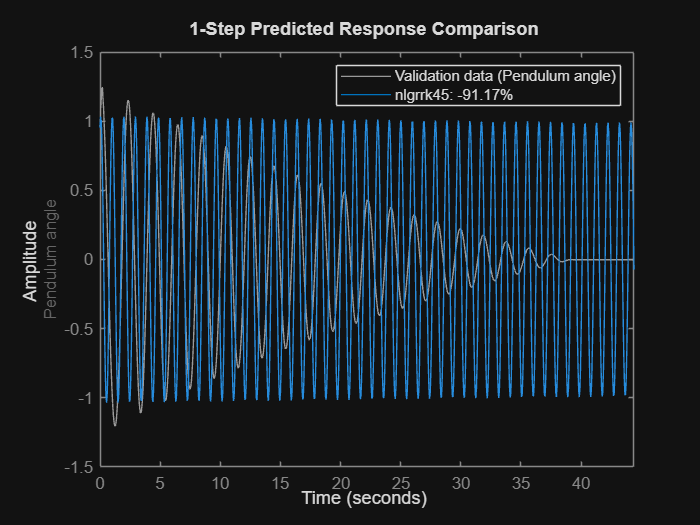


% C. Model computed with adaptive Runge-Kutta 45 ODE solver.
nlgrrk45 = nlgr;
nlgrrk45.SimulationOptions.Solver = 'ode45';     % Runge-Kutta 45.

figure(999);
compare(z, nlgrrk45, 1, ...
   compareOptions('InitialCondition', 'model'));

nlgrrk45 = setpar(nlgrrk45, 'Fixed', {false false false});

We finally use the Runge-Kutta 45 solver (ode45).

opt = nlgreyestOptions('Display', 'on');
trk45 = clock;
nlgrrk45 = nlgreyest(z, nlgrrk45, opt);   % Perform parameter estimation.
trk45 = etime(clock, trk45);
figure(9999);

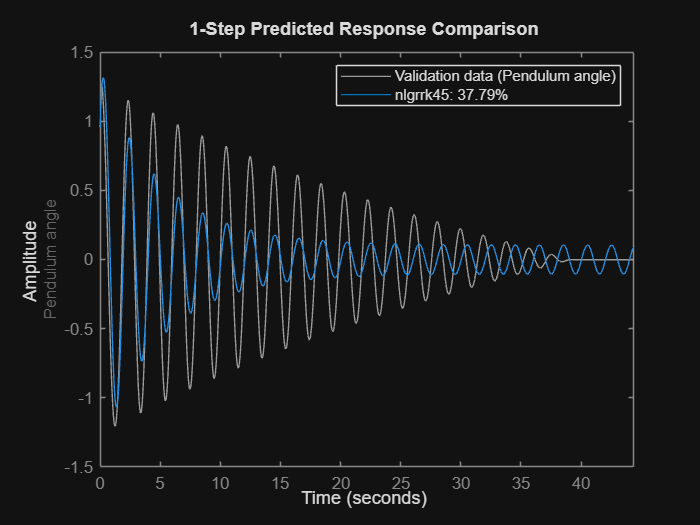

compare(z, nlgrrk45, 1, ...
   compareOptions('InitialCondition', 'model'));

nlgrrk45.Parameters

ans = 3×1 struct array with fields:
    Name
    Unit
    Value
    Minimum
    Maximum
    Fixed


fpe(nlgrrk45);

    0.0759



nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'pendulum' (MATLAB file):

   dx/dt = F(t, x(t), p1, ..., p3)
    y(t) = H(t, x(t), p1, ..., p3) + e(t)

 with 0 input(s), 2 state(s), 1 output(s), and 3 free parameter(s) (out of 3).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: 86.86%                                                  
FPE: 0.003384, MSE: 0.003361                                                    

Model Properties


nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'pendulum' (MATLAB file):

   dx/dt = F(t, x(t), p1, ..., p3)
    y(t) = H(t, x(t), p1, ..., p3) + e(t)

 with 0 input(s), 2 state(s), 1 output(s), and 3 free parameter(s) (out of 3).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: 86.9%                                                   
FPE: 0.003367, MSE: 0.003344                                                    

Model Properties


ans = 3×1 struct array with fields:
    Name
    Unit
    Value
    Minimum
    Maximum
    Fixed


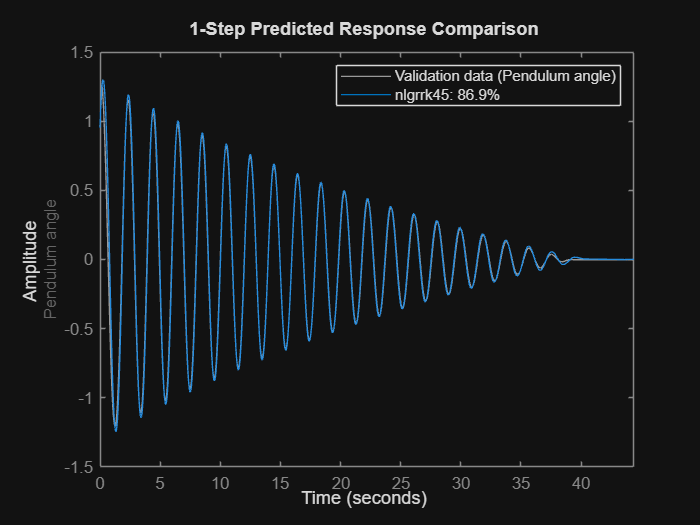

nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'pendulum' (MATLAB file):

   dx/dt = F(t, x(t), p1, ..., p3)
    y(t) = H(t, x(t), p1, ..., p3) + e(t)

 with 0 input(s), 2 state(s), 1 output(s), and 3 free parameter(s) (out of 3).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: 86.9%                                                   
FPE: 0.003367, MSE: 0.003344                                                    

Model Properties


nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'pendulum' (MATLAB file):

   dx/dt = F(t, x(t), p1, ..., p3)
    y(t) = H(t, x(t), p1, ..., p3) + e(t)

 with 0 input(s), 2 state(s), 1 output(s), and 3 free parameter(s) (out of 3).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: 86.9%                                                   
FPE: 0.003367, MSE: 0.003344                                                    

Model Properties


ans = 3×1 struct array with fields:
    Name
    Unit
    Value
    Minimum
    Maximum
    Fixed



for i = 1:2
    nlgrrk45 = nlgreyest(z,nlgrrk45, opt)
    nlgrrk45 = pem(z,nlgrrk45, opt)

    nlgrrk45.Parameters
    figure(i),clf;
        compare(z, nlgrrk45, 1, ...
        compareOptions('InitialCondition', 'model'));
end


y_init = D05_13_h05_Ef_An_R01.data(1,2);
y = D05_13_h05_Ef_An_R01.data(2:end,2);
z = iddata(y, [], h, 'Name', 'Pendulum');
z.OutputName = {'Pendulum angle'};
z.OutputUnit = {'rad'};
z.Tstart = 0;
z.TimeUnit = 's';

[a,b,c]=nlgrrk45.Parameters.Value

a = 10.8795

b = 0.0393

c = 0.1051


FileName      = 'pendulum';        % File describing the model structure.
Order         = [1 0 2];             % Model orders [ny nu nx].
Parameters    = [a; b; c];   % Initial parameters. %Jf,c_u,c_v
InitialStates = [y(1);(y(1)-y_init)/h]              % Initial initial states.

InitialStates =     0.0176
   -1.4074


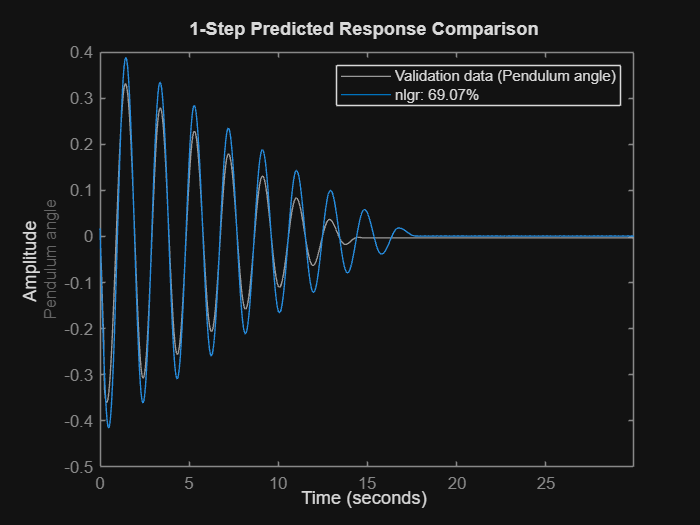

Ts            = 0;                   % Time-continuous system.
nlgr = idnlgrey(FileName, Order, Parameters, InitialStates, Ts);
nlgr.OutputName = {'Pendulum angle'};
nlgr.OutputUnit = {'rad'};
nlgr.TimeUnit = 's';
nlgr = setinit(nlgr, 'Name', {'Pendulum angle' 'Pendulum velocity'});
nlgr = setinit(nlgr, 'Unit', {'rad' 'rad/s'});
nlgr = setpar(nlgr, 'Name', {'K1' 'K2' 'K3'});
nlgr = setpar(nlgr, 'Unit', {'kg' 'idk' 'idk'});
nlgr = setpar(nlgr, 'Minimum', {eps(0) eps(0) -inf});   % All parameters > 0.
nlgr = setpar(nlgr, 'Maximum', {inf inf inf});   % All parameters > 0.

nlgr.SimulationOptions.Solver = 'ode45';     % Runge-Kutta 45.

figure(1), clf;
compare(z, nlgr, 1, ...
   compareOptions('InitialCondition', 'model'));